# 自举开关的失真分析

## 导通电流的模型建立

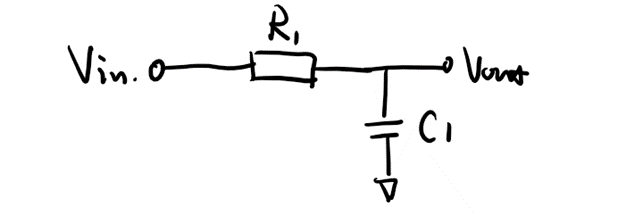

### 1. 基本参数的设置

clc
clear
C1 = 38.72e-12;
Ron = 182;
tau = C1*Ron

tau = 7.0470e-09

num = [C1, 0];
den = [tau, 1];
sys_id = tf(num, den)

sys_id =
 
    3.872e-11 s
  ---------------
  7.047e-09 s + 1
 
Continuous-time transfer function.



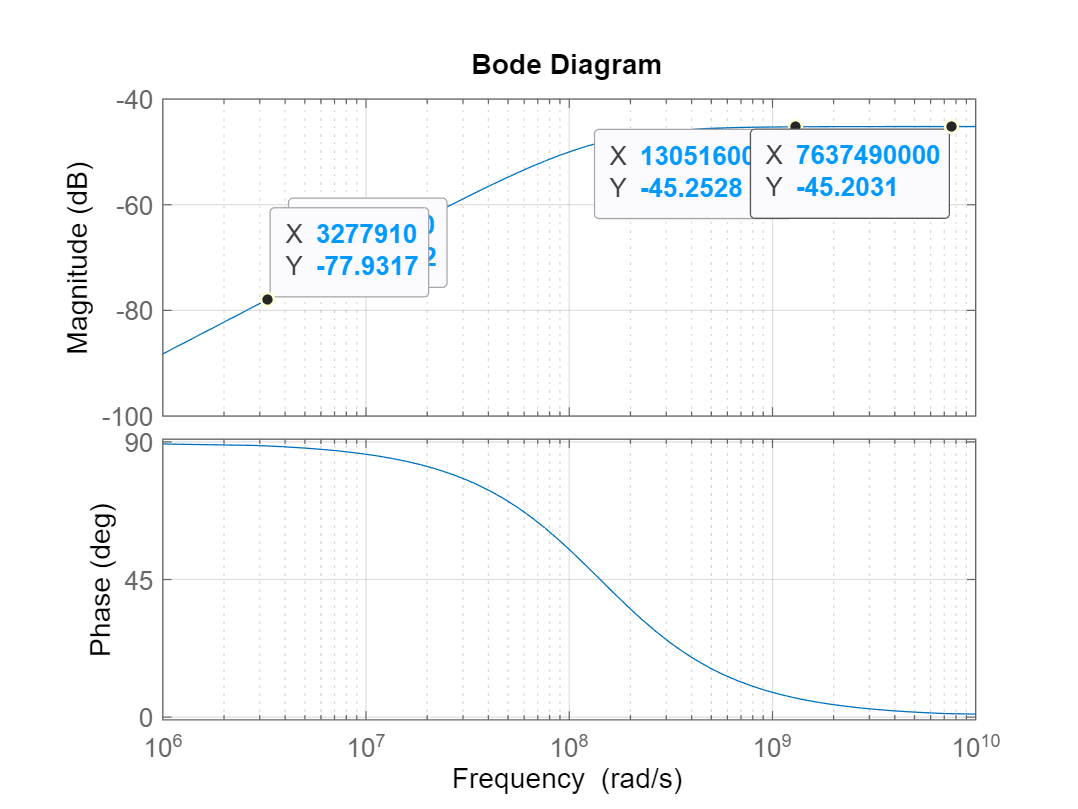

figure()
bode(sys_id);
grid on;

% [mag, phase, wout] = bode(sys_id);
% figure()
% subplot(2,1,1)
% semilogx(wout, mag2db(mag(:,:)));
% grid on;
% ylim([-100, -40])
% subplot(2,1,2)
% semilogx(wout, phase(:,:));
% grid on;

### 2. 时域响应对比

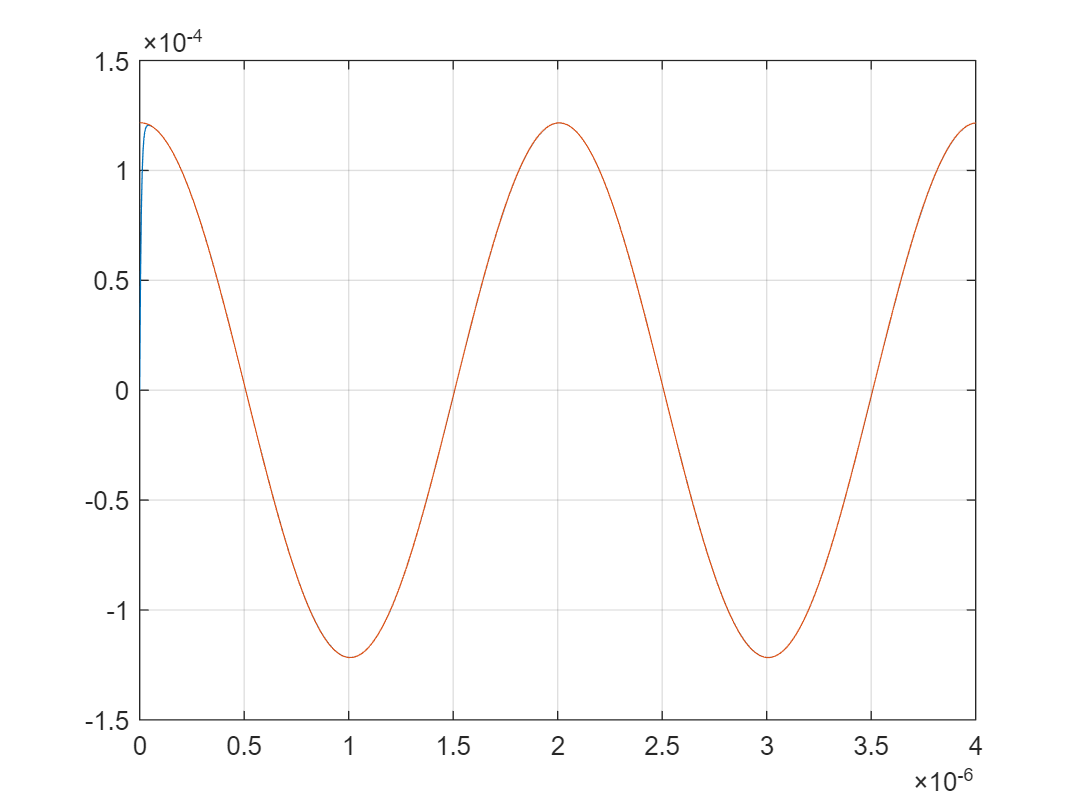

t = linspace(0,4e-6,1000);
Fin = 500e3;
win = 2*pi*Fin;
vin = sin(win.*t);
id_s = lsim(sys_id, vin, t);
id_c = C1*win*cos(win.* (t - C1*Ron));
figure()
plot(t,id_s, t,id_c);
grid on